clear; close all; clc; % initializes workspace, figures, and command window

# 固有値分解と二次形式の標準形

## 本章の目的

前章では，分散共分散行列の固有ベクトルがPCAにおける主成分係数に対応し，データの分散をもっともよく説明する主軸方向を表すことを解説しました．また，分散共分散行列の固有値はPCAにおける主成分分散に対応し，それぞれの主軸方向に含まれる分散であることを解説しました．さらに，分散共分散行列の固有値分解を解説し，分散共分散行列$V$の固有ベクトルを列にもつ行列$Q$と固有値を対角成分にもつ対角行列$D$を用いて，


$$V=\mathit{QD}Q^T$$


と表すことができることを紹介しました．

本章では，正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$を固有値分解を用いて式変形して，$S=\left(u\prime ,\mathit{Du}\prime \right)$という式を導出します（ただし，$u\prime =Q^T u$）．そして，$S=\left(u,\mathit{Vu}\right)$と$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフを比較して，互いに回転させた関係であることを解説します．

## データの準備

引き続き，「米国３２９都市における生活満足度」のデータセットを用います．また，「健康」と「芸術」に関する指標を用いて，変数とする二変量データとして解説していきます．さらに，説明を簡単にするために，平均値が０，標準偏差が１になるように正規化しておきます．

load cities.mat;
scores_health_norm = normalize(ratings(:, 3)); % extracts scores on healt (the 3rd  column) and normalizes it
scores_arts_norm = normalize(ratings(:, 7)); % extracts scores on arts (the 7th column) and normalizes it

説明のため，データ行列$X$を定義します．各行が「健康」および「芸術」に関する正規化された評価値に対応し，各列が観測に対応します．

X = [scores_health_norm scores_arts_norm]'

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

データ行列$X$の$i$番目の観測を$x^{\left(i\right)} =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1^{\left(\mathrm{i}\right)} \\
{\mathrm{x}}_2^{\left(\mathrm{i}\right)} 
\end{array}\right\rbrack$と表します．ここで，${\mathrm{x}}_1^{\left(\mathrm{i}\right)}$および${\mathrm{x}}_2^{\left(\mathrm{i}\right)}$はそれぞれデータ行列$X$の$i$番目の観測における一番目の変数（「健康」）と二番目の変数（「芸術」）の標準化された評価値です．

### 前章の復習

前章の復習をかねて，データ行列$X$の分散共分散行列$V$を求め，その固有ベクトルおよび固有値を求めておきます．

#### 分散共分散行列

データ行列$X$の分散共分散行列$V$は

V = cov(X',1)

V =     0.9970    0.8632
    0.8632    0.9970


となります．

#### 分散共分散行列$V$の固有ベクトルおよび固有値

eig()関数を用いて以下のように求めることができました．

[Q,D] = eig(V)

Q =     0.7071   -0.7071
   -0.7071   -0.7071


D =     0.1338         0
         0    1.8601


ここで，行列$Q$の各列が分散共分散行列$V$の固有ベクトルです．また，行列$D$は対角成分が固有値となる対角行列です．対角成分が左上から降順に並ぶように並び替えます．

[d,ind] = sort(diag(D),'descend');
D = diag(d)

D =     1.8601         0
         0    0.1338


固有ベクトルも対応するように，$Q$の列を左側から順次並べ替えていきます．

Q = Q(:,ind)

Q =    -0.7071    0.7071
   -0.7071   -0.7071


## 正射影ベクトルの長さの分散$\mathrm{S}=\left(u,\mathit{Vu}\right)$の二次形式とその標準形

ここでは，正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$を，分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いて式変形していきます．

### 二次形式

まずはじめに，正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$を成分で表記し，$S=\left(u,\mathit{Vu}\right)$が二次形式と呼ばれる多項式のひとつであることを確認します．

すでに見てきたように，正射影ベクトルの長さの分散$S$は，データの分散共分散行列$V$を用いて


$$S=\left(u,\mathit{Vu}\right)$$


と表されます．ただし，$u$はデータ空間上の任意の方向を表す単位ベクトル$u=\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack$であり，その長さは$\left\|u\right\|=\sqrt{{{\mathrm{u}}_1 }^2 +{{\mathrm{u}}_2 }^2 }=1$です．このとき，$S$を成分で書き下すと以下のようになります．


$$\begin{array}{l}
\mathrm{S}=\left(\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
{\mathrm{v}}_{11}  & {\mathrm{v}}_{12} \\
{\mathrm{v}}_{21}  & {\mathrm{v}}_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;={\mathrm{v}}_{11} {{\mathrm{u}}_1 }^2 +\left({\mathrm{v}}_{12} +{\mathrm{v}}_{21} \right){\mathrm{u}}_1 {\mathrm{u}}_2 +{\mathrm{v}}_{22} {{\mathrm{u}}_2 }^2 
\end{array}$$


ここで，分散共分散行列の定義


$$V=\left\lbrack \begin{array}{cc}
\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} \right)}^2  & \frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \\
\frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {{\mathrm{x}}_1 }^{\left(\mathrm{i}\right)} {{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)}  & \frac{1}{\mathrm{N}}\sum_{i=1}^{\mathrm{N}} {\left({{\mathrm{x}}_2 }^{\left(\mathrm{i}\right)} \right)}^2 
\end{array}\right\rbrack$$


より，非対角成分は等しいことがわかります（${\mathrm{v}}_{12} ={\mathrm{v}}_{21}$）．そこで，$\mathrm{S}=\left(u,\mathit{Vu}\right)$は以下のように書き換えることができます．


$$\begin{array}{l}
\mathrm{S}=\left(u,\mathit{Vu}\right)\\
\;\;\;={\mathrm{v}}_{11} {{\mathrm{u}}_1 }^2 +2{\mathrm{v}}_{12} {\mathrm{u}}_1 {\mathrm{u}}_2 +{\mathrm{v}}_{22} {{\mathrm{u}}_2 }^2 
\end{array}$$


さて，上式を${\mathrm{u}}_1$および${\mathrm{u}}_2$の多項式としてみると，**二次の項（**${{\mathrm{u}}_1 }^2$，${\mathrm{u}}_1 {\mathrm{u}}_2$，${{\mathrm{u}}_2 }^2$**）のみ**からなりなっているのがわかります．このような多項式を**二次形式**といいます（※１）．二次形式は二次式と異なることに注意してください．二次式は二次およびそれよりも低次の項を含む多項式です．例えば$3{{\mathrm{u}}_1 }^2 +2{\mathrm{u}}_1 {\mathrm{u}}_2 +8{\mathrm{u}}_2 +5$は，二次の項の他に一次（$8{\mathrm{u}}_2$）やゼロ次（$5$）の項を含む多項式ですので，二次式ですが，二次形式ではありません．

### 標準形

二次形式には標準形と呼ばれる特別な形式が存在します．たとえば，$\mathrm{S}=\left(u,\mathit{Vu}\right)$において，${\mathrm{v}}_{12} ={\mathrm{v}}_{21} =0$だった場合，


$$\mathrm{S}=$$

$${\mathrm{v}}_{11} {{\mathrm{u}}_1 }^2 +{\mathrm{v}}_{22} {{\mathrm{u}}_2 }^2$$


となり，標準形と呼ばれる形になります．このように，二乗の項のみからなる二次形式を二次形式の**標準形**といいます．一般に，${{\mathrm{x}}_1 }^2$と${{\mathrm{x}}_2 }^2$の項からなる二次形式の標準形


$${\mathrm{a}}_1 {{\mathrm{x}}_1 }^2 +{\mathrm{a}}_2 {{\mathrm{x}}_2 }^2$$


は，それぞれの係数を対角成分とする対角行列$A=\left\lbrack \begin{array}{cc}
{\mathrm{a}}_{11}  & 0\\
0 & {\mathrm{a}}_{22} 
\end{array}\right\rbrack$を用いて


$${\mathrm{a}}_1 {{\mathrm{x}}_1 }^2 +{\mathrm{a}}_2 {{\mathrm{x}}_2 }^2 =\left(x,Ax\right)$$


と表すことができます．ただし，$x=\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$です．

### 二次形式の標準化

二次形式は適切に変数変換することで標準形に変換することができます．これを二次形式の標準化といいます．実際に，二次形式$\mathrm{S}=\left(u,\mathit{Vu}\right)$を標準化してみましょう．標準化のためには，前セクションで見てきた分散共分散$V$の固有値分解が活躍します．行列$V$の固有値分解とは，対角成分が$V$の固有値からなる対角行列$D$と，各列が行列$V$の固有ベクトルからなる行列$Q$を用いて，分散共分散行列$V$を


$$V=\mathit{QD}Q^{-1}$$


と表すことでした．さらに分散共分散行列$V$は対称行列であることから，


$$V=\mathit{QD}Q^T$$


となります．これを$\left(u,\mathit{Vu}\right)$に代入すると，


$$\begin{array}{l}
\mathrm{S}=\left(u,\mathit{QD}Q^T u\right)\\
\;\;\;=\left(Q^T u,DQ^T u\right)
\end{array}$$


となります．ここで，$Q^T u=u\prime =\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \prime \\
{\mathrm{u}}_2 \prime 
\end{array}\right\rbrack$とおくと


$$\mathrm{S}=\left(u\prime ,\mathit{Du}\prime \right)$$


とすることができます．$D$は非対角成分がゼロの対角行列なので，上式は二次形式となります．実際に成分で書き下して確認してみると，


$$\begin{array}{l}
\mathrm{S}=\left(\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \prime \\
{\mathrm{u}}_2 \prime 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \prime \\
{\mathrm{u}}_2 \prime 
\end{array}\right\rbrack \right)\\
\;\;\;=\lambda_1 {{\mathrm{u}}_1 \prime }^2 +\lambda_2 {{\mathrm{u}}_2 \prime }^2 
\end{array}$$


となり，二次形式の標準形であることがわかります．

### ※１　二次形式と対称行列

ここで，対称でない行列についても適切な変換をすれば，対称行列を用いた二次形式にすることができます．いま，対称でない行列$A=\left\lbrack \begin{array}{cc}
{\mathrm{a}}_{11}  & {\mathrm{a}}_{12} \\
{\mathrm{a}}_{21}  & {\mathrm{a}}_{22} 
\end{array}\right\rbrack$を考えます（${\mathrm{a}}_{12} \not= {\mathrm{a}}_{21}$）．この行列を用いた二次形式を


$$\begin{array}{l}
\left(x,\mathit{Ax}\right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
{\mathrm{a}}_{11}  & {\mathrm{a}}_{12} \\
{\mathrm{a}}_{21}  & {\mathrm{a}}_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\mathrm{a}}_{11} {{\mathrm{x}}_1 }^2 +\left({\mathrm{a}}_{12} +{\mathrm{a}}_{\left.21\right)} \right){\mathrm{x}}_{12} {\mathrm{x}}_{21} +{\mathrm{a}}_{22} {{\mathrm{x}}_{22} }^2 
\end{array}$$


とします．ここで，$\left({\mathrm{a}}_{12} +{\mathrm{a}}_{21} \right)/2={\mathrm{a}}_{12} \prime$として，${\mathrm{a}}_{12}$と${\mathrm{a}}_{21}$をそれぞれ${\mathrm{a}}_{12} \prime$に置き換えた行列を$A\prime =\left\lbrack \begin{array}{cc}
a_{11}  & a_{12} \prime \\
a_{12} \prime  & a_{22} 
\end{array}\right\rbrack$とします．このとき，


$${A\prime }^T =A\prime$$


が成立します．つまり，$A\prime$は対称行列です．この$A\prime$を使った二次形式は，


$$\begin{array}{l}
\left(x,A\prime x\right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
{\mathrm{a}}_{11}  & {\mathrm{a}}_{12} \prime \\
{\mathrm{a}}_{12} \prime  & {\mathrm{a}}_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\mathrm{a}}_{11} {{\mathrm{x}}_1 }^2 +2{\mathrm{a}}_{12} \prime {\mathrm{x}}_{12} {\mathrm{x}}_{21} +{\mathrm{a}}_{22} {{\mathrm{x}}_{22} }^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\mathrm{a}}_{11} {{\mathrm{x}}_1 }^2 +\left({\mathrm{a}}_{12} +{\mathrm{a}}_{\left.21\right)} \right){\mathrm{x}}_{12} {\mathrm{x}}_{21} +{\mathrm{a}}_{22} {{\mathrm{x}}_{22} }^2 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(x,\mathit{Ax}\right)
\end{array}$$


となります．すなわち，対称でない行列$A$を使った二次形式でも，適切な変換をすることで，対称行列を使った二次形式として表すことができます．以降では，すべて二次形式は対称行列を用いて表すことにします．なお，前述したように分散共分散行列$V$はその定義より必ず対称行列となります．

## 二次形式$S=\left(u,\mathit{Vu}\right)$と標準形$S=\left(Q^T u,DQ^T u\right)$の比較

ここでは，$S=\left(u,\mathit{Vu}\right)$と$S=\left(Q^T u,DQ^T u\right)$のグラフを比較して，それぞれがお互いに軸を回転させた関係にあることを確認します．

### 二次形式$\mathrm{S}=\left(u\prime ,\mathit{Du}\prime \right)$のグラフ

まずは二次形式のグラフを作成します．前述したように，二次形式$S=\left(u,\mathit{Vu}\right)$は


$$\begin{array}{l}
\mathrm{S}=\left(\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
{\mathrm{v}}_{11}  & {\mathrm{v}}_{12} \\
{\mathrm{v}}_{12}  & {\mathrm{v}}_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;={\mathrm{v}}_{11} {{\mathrm{u}}_1 }^2 +2{\mathrm{v}}_{12} {\mathrm{u}}_1 {\mathrm{u}}_2 +{\mathrm{v}}_{22} {{\mathrm{u}}_2 }^2 
\end{array}$$


と表すことができます．ここで，$u$はデータ空間上の任意の方向を表す単位ベクトルであり，$\left\|u\right\|=\sqrt{{{\mathrm{u}}_1 }^2 +{{\mathrm{u}}_2 }^2 }=1$です．また，分散共分散行列$V=\left\lbrack \begin{array}{cc}
{\mathrm{v}}_{11}  & {\mathrm{v}}_{12} \\
{\mathrm{v}}_{12}  & {\mathrm{v}}_{22} 
\end{array}\right\rbrack$としました．このとき，$S=\left(u,\mathit{Vu}\right)$のグラフは


$$\begin{array}{l}
{\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)\\
{{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1
\end{array}$$


を同時に満たす点になります．ただし，$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)={\mathrm{v}}_{11} {{\mathrm{x}}_1 }^2 +2\times {\mathrm{v}}_{12} {\mathrm{x}}_1 {\mathrm{x}}_2 +{\mathrm{v}}_{22} {{\mathrm{x}}_2 }^2$です．以下に，$V=\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack$としたときのグラフを示します．

figure('Name','Fig.6-1: Visualazation of S=(u,Du)');
t1_upper = linspace(0,pi,100)';
x1_upper = cos(t1_upper);
x2_upper = sin(t1_upper);
x3_upper = [x1_upper x2_upper]*V*[x1_upper x2_upper]';
x3_upper = diag(x3_upper);
plot3(x1_upper,x2_upper,x3_upper,'r-'); hold on;

t1_lower = linspace(pi,2*pi,100)';
x1_lower = cos(t1_lower);
x2_lower = sin(t1_lower);
x3_lower = [x1_lower x2_lower]*V*[x1_lower x2_lower]';
x3_lower = diag(x3_lower);
plot3(x1_lower,x2_lower,x3_lower,'r-');

t = linspace(0,2*pi,100);
plot3(cos(t),sin(t),zeros(size(t)),'k--');

[x3_max, max_ind] = max(x3_lower);
x1_max = x1_upper(max_ind);
x2_max = x2_upper(max_ind);
arrow3([0 0 0],[x1_max,x2_max,0],'r--');

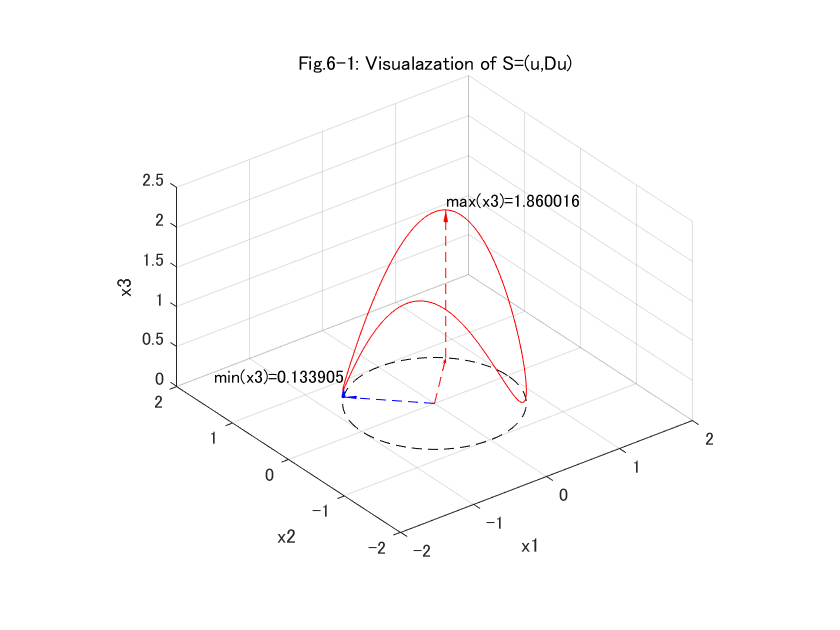

arrow3([x1_max,x2_max,0],[x1_max,x2_max,x3_max],'r--');
str_max = sprintf('max(x3)=%f',x3_max); text(x1_max,x2_max,x3_max,str_max,'VerticalAlignment','bottom');

[x3_min, min_ind] = min(x3_lower);
x1_min = x1_upper(min_ind);
x2_min = x2_upper(min_ind);
arrow3([0 0 0],[x1_min,x2_min,0],'b--');
arrow3([x1_min,x2_min,0],[x1_min,x2_min,x3_min],'b--');
str_min = sprintf('min(x3)=%f',x3_min); text(x1_min,x2_min,x3_min,str_min,...
                                          'VerticalAlignment','bottom',...
                                          'HorizontalAlignment','right');

title('Fig.6-1: Visualazation of S=(u,Du)'); hold on;
xlim([-2 2]); ylim([-2 2]); zlim([0 2.5]); grid on;
xlabel('x1'); ylabel('x2'); zlabel('x3');

赤い曲線が$S=\left(u,\mathit{Vu}\right)$を表す曲線です．黒い点線は${\mathrm{x}}_1 {\mathrm{x}}_2$平面上の単位円を表します．前章で述べたように，$S=\left(u,\mathit{Vu}\right)$は分散共分散行列$V$の一つ目の固有ベクトルが示す方向で最大値をとります（赤点線矢印）．また，ふたつの固有ベクトルが示す方向で最小値になります（青点線矢印）．

### 標準形$\mathrm{S}=\left(u\prime ,\mathit{Du}\prime \right)$のグラフ

つづいて，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフを作成します．前述したように，標準形$S=\left(u\prime ,\mathit{Du}\prime \right)$は


$$\begin{array}{l}
\mathrm{S}=\left(\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \prime \\
{\mathrm{u}}_2 \prime 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \prime \\
{\mathrm{u}}_2 \prime 
\end{array}\right\rbrack \right)\\
\;\;\;=\lambda_1 {{\mathrm{u}}_1 \prime }^2 +\lambda_2 {{\mathrm{u}}_2 \prime }^2 
\end{array}$$


と表すことができます．ここで，$u\prime$は$u\prime =Q^T u$であり，$\left\|u\right\|=\sqrt{{{\mathrm{u}}_1 }^2 +{{\mathrm{u}}_2 }^2 }=1$です．また，$D=$$\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$であり，$\lambda_1$および$\lambda_2$は分散共分散行列の固有値です（$\lambda_1 >\lambda_2$）．

ベクトル$u\prime$の長さ$\left\|u\prime \right\|$は


$$\left\|u\prime \right\|=\mathrm{det}\left(Q^T \right)\left\|u\right\|$$


となります．ここで$\mathrm{det}\left(Q^T \right)=\mathrm{det}\left(Q\right)=1$（※前章参照），$\left\|u\right\|=1$より，


$$\left\|u\prime \right\|=1$$


となります．

このとき，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは


$$\begin{array}{l}
{\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)\\
{{\mathrm{x}}_1 \prime }^2 +{{\mathrm{x}}_2 \prime }^2 =1
\end{array}$$


を同時に満たす点になります．ただし，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\lambda_1 {{\mathrm{x}}_1 \prime }^2 +\lambda_2 {{\mathrm{x}}_2 \prime }^2$です．以下に，$D=\left\lbrack \begin{array}{cc}
1\ldotp 8601 & 0\\
0 & 0\ldotp 1338
\end{array}\right\rbrack$としたときのグラフを示します．

figure('Name','Fig.6-2: Visualazation of S=(u'',Du'')');
t1_upper = linspace(0,pi,100)';
x1_upper = cos(t1_upper);
x2_upper = sin(t1_upper);
x3_upper = [x1_upper x2_upper]*D*[x1_upper x2_upper]';
x3_upper = diag(x3_upper);
plot3(x1_upper,x2_upper,x3_upper,'r-'); hold on;

t1_lower = linspace(pi,2*pi,100)';
x1_lower = cos(t1_lower);
x2_lower = sin(t1_lower);
x3_lower = [x1_lower x2_lower]*D*[x1_lower x2_lower]';
x3_lower = diag(x3_lower);
plot3(x1_lower,x2_lower,x3_lower,'r-'); hold on;

t = linspace(0,2*pi,100);
plot3(cos(t),sin(t),zeros(size(t)),'k--');

[x3_max, max_ind] = max(x3_lower);
x1_max = x1_upper(max_ind);
x2_max = x2_upper(max_ind);
arrow3([0 0 0],[x1_max,x2_max,0],'r--');

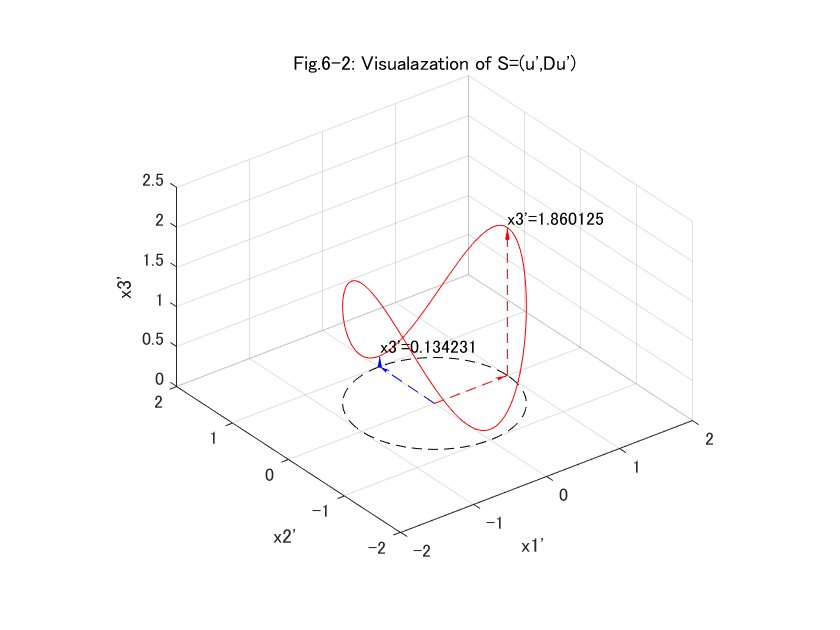

arrow3([x1_max,x2_max,0],[x1_max,x2_max,x3_max],'r--');
str_max = sprintf('x3''=%f',x3_max); text(x1_max,x2_max,x3_max,str_max,'VerticalAlignment','bottom');

[x3_min, min_ind] = min(x3_lower);
x1_min = x1_upper(min_ind);
x2_min = x2_upper(min_ind);
arrow3([0 0 0],[x1_min,x2_min,0],'b--');
arrow3([x1_min,x2_min,0],[x1_min,x2_min,x3_min],'b--');
str_min = sprintf('x3''=%f',x3_min); text(x1_min,x2_min,x3_min,str_min,'VerticalAlignment','bottom');

title('Fig.6-2: Visualazation of S=(u'',Du'')')
xlim([-2 2]); ylim([-2 2]); zlim([0 2.5]); grid on;
xlabel('x1'''); ylabel('x2'''); zlabel('x3''');

赤い曲線が$S=\left(u\prime ,\mathit{Du}\prime \right)$を表す曲線です．黒い点線は${\mathrm{x}}_1 \prime {\mathrm{x}}_2 \prime$平面上の単位円を表します．$S=\left(u\prime ,\mathit{Du}\prime \right)$は$\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\left(\pm 1,0\right)$で最大値をとり（赤点線矢印），$\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\left(0,\pm 1\right)$で最小値になります（青点線矢印）．

### 二次形式$S=\left(u,\mathit{Vu}\right)$と標準形$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフ比較

あらためて，ふたつのグラフを比較してみます．

figure('Name','Fig.6-3: S=(u,Vu) vs. S=(u'',Du'')');
subplot(1,2,1);
t1_upper = linspace(0,pi,100)';
x1_upper = cos(t1_upper);
x2_upper = sin(t1_upper);
x3_upper = [x1_upper x2_upper]*V*[x1_upper x2_upper]';
x3_upper = diag(x3_upper);
plot3(x1_upper,x2_upper,x3_upper,'r-'); hold on;

t1_lower = linspace(pi,2*pi,100)';
x1_lower = cos(t1_lower);
x2_lower = sin(t1_lower);
x3_lower = [x1_lower x2_lower]*V*[x1_lower x2_lower]';
x3_lower = diag(x3_lower);
plot3(x1_lower,x2_lower,x3_lower,'r-'); hold on;

t = linspace(0,2*pi,100);
plot3(cos(t),sin(t),zeros(size(t)),'k--');

[x3_max, max_ind] = max(x3_lower);
x1_max = x1_upper(max_ind);
x2_max = x2_upper(max_ind);
arrow3([0 0 0],[x1_max,x2_max,0],'r--');

arrow3([x1_max,x2_max,0],[x1_max,x2_max,x3_max],'r--');
str_max = sprintf('max(x3)=%f',x3_max); text(x1_max,x2_max,x3_max,str_max,'VerticalAlignment','bottom');

[x3_min, min_ind] = min(x3_lower);
x1_min = x1_upper(min_ind);
x2_min = x2_upper(min_ind);
arrow3([0 0 0],[x1_min,x2_min,0],'b--');
arrow3([x1_min,x2_min,0],[x1_min,x2_min,x3_min],'b--');
str_min = sprintf('min(x3)=%f',x3_min); text(x1_min,x2_min,x3_min,str_min,...
                                          'VerticalAlignment','bottom',...
                                          'HorizontalAlignment','right');

title('Fig.6-3A: S=(u,Du)')
xlim([-2 2]); ylim([-2 2]); zlim([0 2.5]); grid on;
xlabel('x1'); ylabel('x2'); zlabel('x3');

subplot(1,2,2);
t1_upper = linspace(0,pi,100)';
x1_upper = cos(t1_upper);
x2_upper = sin(t1_upper);
x3_upper = [x1_upper x2_upper]*D*[x1_upper x2_upper]';
x3_upper = diag(x3_upper);
plot3(x1_upper,x2_upper,x3_upper,'r-'); hold on;

t1_lower = linspace(pi,2*pi,100)';
x1_lower = cos(t1_lower);
x2_lower = sin(t1_lower);
x3_lower = [x1_lower x2_lower]*D*[x1_lower x2_lower]';
x3_lower = diag(x3_lower);
plot3(x1_lower,x2_lower,x3_lower,'r-'); hold on;

t = linspace(0,2*pi,100);
plot3(cos(t),sin(t),zeros(size(t)),'k--');

[x3_max, max_ind] = max(x3_lower);
x1_max = x1_upper(max_ind);
x2_max = x2_upper(max_ind);
arrow3([0 0 0],[x1_max,x2_max,0],'r--');

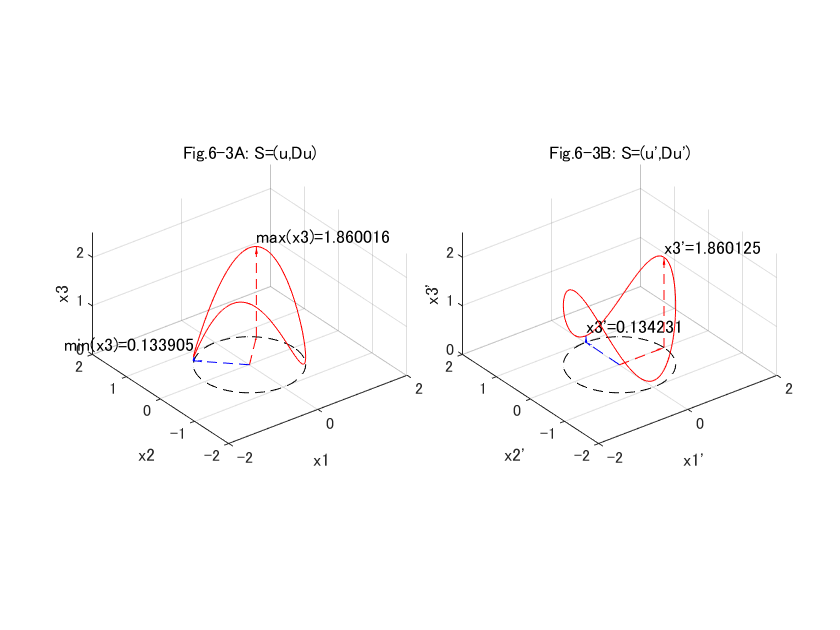

arrow3([x1_max,x2_max,0],[x1_max,x2_max,x3_max],'r--');
str_max = sprintf('x3''=%f',x3_max); text(x1_max,x2_max,x3_max,str_max,'VerticalAlignment','bottom');

[x3_min, min_ind] = min(x3_lower);
x1_min = x1_upper(min_ind);
x2_min = x2_upper(min_ind);
arrow3([0 0 0],[x1_min,x2_min,0],'b--');
arrow3([x1_min,x2_min,0],[x1_min,x2_min,x3_min],'b--');
str_min = sprintf('x3''=%f',x3_min); text(x1_min,x2_min,x3_min,str_min,'VerticalAlignment','bottom');

title('Fig.6-3B: S=(u'',Du'')')
xlim([-2 2]); ylim([-2 2]); zlim([0 2.5]); grid on;
xlabel('x1'''); ylabel('x2'''); zlabel('x3''');

左図が$S=\left(u,\mathit{Vu}\right)$のグラフで，右図が$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフを表します．それぞれのグラフで最大値および最小値となる座標に注目すると，$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは${\mathrm{x}}_1 \prime$軸上および${\mathrm{x}}_2 \prime$軸上でそれぞれ最大値および最小値となっています．$S=\left(u\prime ,\mathit{Du}\prime \right)$のグラフは座標軸上で最大および最小となるように，$S=\left(u,\mathit{Vu}\right)$のグラフを回転させたものと言えます．

#### 標準形$S=\left(u\prime ,\mathit{Du}\prime \right)$のメリット

標準形$S=\left(u\prime ,\mathit{Du}\prime \right)$のメリットは，そのグラフの最大値と最小値を式から直接読み取るころができることです．

たとえば，


$$\begin{array}{l}
{\mathrm{x}}_3 \prime =g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1\ldotp 8601{{\mathrm{x}}_1 \prime }^2 +0\ldotp 1338{{\mathrm{x}}_2 \prime }^2 \\
{{\mathrm{x}}_1 \prime }^2 +{{\mathrm{x}}_2 \prime }^2 =1
\end{array}$$


のグラフを考えます．${\mathrm{x}}_1 \prime$および${\mathrm{x}}_2 \prime$はともに実数ですから，${{\mathrm{x}}_1 \prime }^2 \ge 0$，${{\mathrm{x}}_2 \prime }^2 \ge 0$となります．したがって，


$$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1\ldotp 8601{{\mathrm{x}}_1 \prime }^2 +0\ldotp 1338{{\mathrm{x}}_2 \prime }^2 >0$$


が常に成立します．また，${{\mathrm{x}}_1 \prime }^2 +{{\mathrm{x}}_2 \prime }^2 =1$から，この関数は${{\mathrm{x}}_1 \prime }^2 =1$かつ${{\mathrm{x}}_2 \prime }^2 =0$のときに最大値$1\ldotp 8601$をとります．さらに，${{\mathrm{x}}_1 \prime }^2 =0$かつ${{\mathrm{x}}_2 \prime }^2 =1$のときに最小値$0\ldotp 1338$になります．すなわち，${\mathrm{x}}_1 \prime$軸上で最大値となり，${\mathrm{x}}_2 \prime$軸上で最小値となります．

## これまでのまとめ

本章では$S=\left(u,\mathit{Vu}\right)$が二次形式と呼ばれる特殊な多項式であることを紹介しました．さらに，分散共分散行列$V$の固有値分解$V=\mathit{QD}Q^T$を用いていると，$S=\left(u,\mathit{Vu}\right)$は$S=\left(u\prime ,\mathit{Du}\prime \right)$という形式に変形することができることを示しました（ただし，$u\prime =Q^T u$）．$S=\left(u\prime ,\mathit{Du}\prime \right)$は標準形とよばれ，そのグラフは$S=\left(u,\mathit{Vu}\right)$を回転させたグラフになることを紹介しました．また，その回転によって，$S=\left(u\prime ,\mathit{Du}\prime \right)$は座標軸上で最大値および最小値をとるにようになることを確認しました．

$S=\left(u,\mathit{Vu}\right)$から$S=\left(u\prime ,\mathit{Du}\prime \right)$への回転こそが，分散共分散行列$V$の固有値分解を用いたPCAの核心部といえます．次章ではこの回転をさらに詳しく見ていきます．